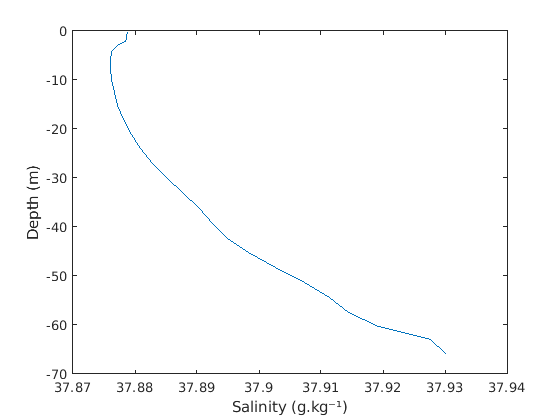

Wind = 10;
date = datetime(1999,12,19);

[KZ,Row,~,z_,Sal,Temp,Uz,Vz] = KsSalTemp2020(Wind, date);

plot(Sal,z_)
xlabel("Salinity (g.kg⁻¹)")
ylabel("Depth (m)")

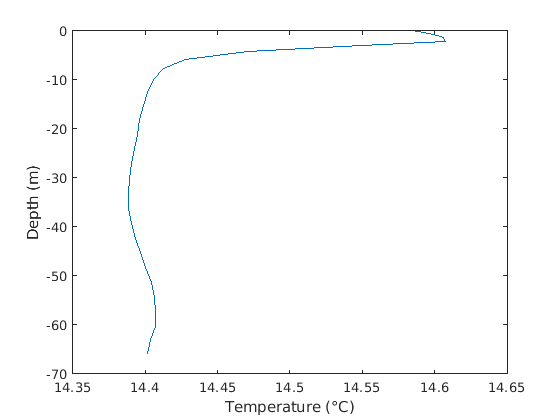

plot(Temp,z_)
xlabel("Temperature (°C)")
ylabel("Depth (m)")


Temp = Temp + 273.15; % °C -> K

Coagulation equation (Burd 2009) :


$$
{\frac{dn(m, t)}{
dt}\,}={\,\frac{\alpha}{2}\int_{0}^{m}
\beta (m_{j}, m-m_{j})n(m-m_{j}, t)n(m_{j}, t) dm_{j}}\\
{\,}{-\alpha n\left(m,t\right)\int_{0}^{\infty}\beta \left(m,m_{j}\right)n\left(m_{j},t\right)dm_{j}}\\
{\,}{-n\left(m,t\right)\frac{w_{s}\left(m\right)}{Z}+I\left(m,t\right)}\\$$


- ${\,\frac{\alpha}{2}\int_{0}^{m}
\beta (m_{j}, m-m_{j})n(m-m_{j}, t)n(m_{j}, t) dm_{j}}$ : collisions that add material in the size range $m$ to $m+dm$

- ${\,}{-\alpha n\left(m,t\right)\int_{0}^{\infty}\beta \left(m,m_{j}\right)n\left(m_{j},t\right)dm_{j}}$ : collisions that removes material in the size range $m$ to $m+dm$

- ${-n\left(m,t\right)\frac{w_{s}\left(m\right)}{Z}$ : loss rate due to sedimentation

- $I(m,t)$ : input rate of new material

### Coagulation kernel $\beta$ (McCave 1984)

Contains info on the mechanism that bring particles together. 

- Brownian motion

- Laminar shear

- Turbulent shear

- Differential sedimentation

d1 = 100e-6;
d2 = 500e-6;
d12 = d1 + d2;

#### Brownian motion

$\beta_{Br}(i,j)=2\pi D_{ij}d_{ij}=\frac{2}{3}\frac{kT}{\mu}\frac{d_{ij}^2}{d_id_j}$  with dimension $L^3T^{-1}$ ($m^3s^{-1}$)

$D_{ij} = D_i + D_j$ with $D_x=\frac{kT}{3\pi\mu d_x}$ the diffusion coefficients ($L^2T^{-1}$)

$k$ : Boltzmann constant $k= 1.38064852 \times  10^{-23} m^2.kg.s^{-2}.K^{-1}$

$T$ : absolute temperature of the water

$\mu$ : dynamic viscosity

$d_i, d_j$ : particle diameter


$$d_{ij} = d_i+d_j$$


unDynamic viscosity computation (Huber2009)

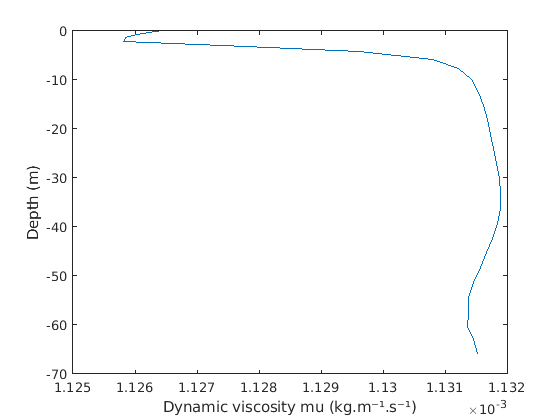

mustart = 1e-6; % kg.m⁻¹.s⁻¹
Tstart = 647.096; % K
rhostar = 322.0; % kg.m⁻³

Hi = [1.67752 2.20462 0.6366564 -0.241605]';
Hij = [5.20094e-1 2.22531e-1 -2.81378e-1 1.61913e-1 -3.25372e-2 0 0;
    8.50895e-2 9.99115e-1 -9.06851e-1 2.57399e-1 0 0 0;
    -1.08374 1.88797 -7.72479e-1 0 0 0 0;
    -2.89555e-1 1.26613 -4.89837e-1 0 6.98452e-2 0 -4.35673e-3;
    0 0 -2.57040e-1 0 0 8.72102e-3 0;
    0 1.20573e-1 0 0 0 0 -5.93264e-4];

Tbar = Temp/Tstart; % adimentional temp (K)
rhobar = Row/rhostar;

EPS0 = 0;
for i = 1:length(Hi)
    EPS0 = EPS0+Hi(i)./Tbar.^(i-1);
end, clear i,

mu0bar = 100*sqrt(Tbar)./EPS0;
clear EPS0 Hi,

EPS1i = 0;
for i = 0:5
    EPS1j = 0;
    for j = 0:6
        EPS1j = EPS1j + Hij(i+1,j+1).*(rhobar-1).^j;
    end, clear j,
    EPS1i = EPS1i + (1./Tbar-1).^i.*EPS1j;
end, clear i,
mu1bar = exp(rhobar.*EPS1i);
clear EPS1i EPS1j Hij,

mubar = mu0bar.*mu1bar;
mu = mubar.*mustart;

plot(mu,z_)
xlabel("Dynamic viscosity mu (kg.m⁻¹.s⁻¹)")
ylabel("Depth (m)")

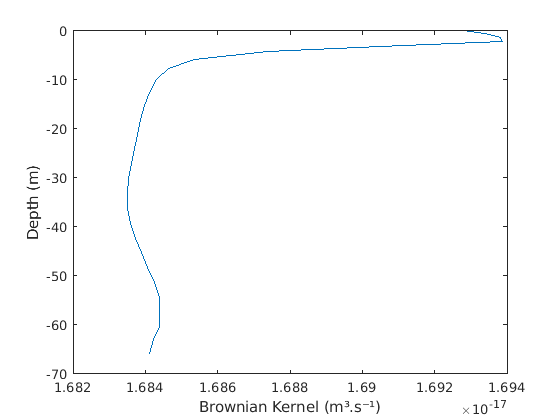

k = 1.38064852e-23;
D1 = k*Temp./(3*pi*mu*d1);
D2 = k*Temp./(3*pi*mu*d2);
D12 = D1 + D2;

Kbr = 2*pi*D12*d12;

plot(Kbr,z_)
xlabel("Brownian Kernel (m³.s⁻¹)")
ylabel("Depth (m)")

$\rightarrow$ à ajouter à la diffusion turbulente ?

clear k mu mu0 mu0bar mu1bar mubar mustart rhobar rhostar Tbar Tstart,

#### Laminar and turbulent shear

$\beta_{LS}(i,j) = \Gamma\frac{d_{ij}^3}{6}$  kernel for laminar shear with $\Gamma = \frac{dU}{dz}$

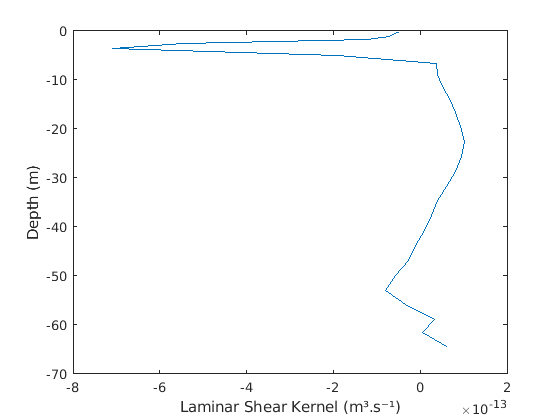

Gamma = (diff(Uz) + diff(Vz))./diff(z_); % s⁻¹
Kls = Gamma .* d12^3./6;
z__ = (z_(1:end-1)+z_(2:end))/2;

plot(Kls,z__)
xlabel("Laminar Shear Kernel (m³.s⁻¹)")
ylabel("Depth (m)")

$\beta_{TS}(i,j) = 0.163d_{ij}^3\sqrt{\frac{\epsilon}{\nu}}$  kernel for turbulent shear with $\epsilon$ the turbulent dissipation rate and $\nu$ the kinematic viscosity

$\epsilon$ ??

Simulation Param

dt_test = 60*60*2;
date = datetime(2020,03,18);
tf = 60*60*24*3;

%% Water column parameters
%% Load hydrodinamic model data
ModeleHydro='2012RHOMA_arome_003.nc';
SauvegardeModeleHydro=['DonneeBase' ModeleHydro(1:end-3)];
load(SauvegardeModeleHydro, 'H0')

%% Water column parameters
% Find depth of the column
Station = 'RN2';
% Load file with indexes corresponding to each stations
stationFile = '../Data/stationIJ_CEREGE.mat';
load(stationFile,'stationIJ');
% Get the indexes of the right station
I0 = stationIJ{stationIJ{:,'station'} == Station,'I0'};
J0 = stationIJ{stationIJ{:,'station'} == Station,'J0'};
L = H0(I0,J0); % depth
clear H0 stationIJ,

N = 50;
dz= L/N;  z=0:dz:L; % z : boundaries of the meshes
z_=(z(1:end-1)+z(2:end))/2; % middle of each mesh  

nMP = 100;
pd = makedist('Normal', 'mu', 450e-6, 'sigma', 50e-6);
sizeMP = random(pd,nMP,1);
sizeMP(sizeMP<1e-6) = 1e-6;
clear pd,
% zInit = linspace(0,L,nPart);
zInitMP = linspace(0,L,nMP);
frag = 0;

wind = 100;
rhoMP = 1000;

[KZ_day,Row_day,z_day,z__day] = KsSalTemp2020(wind, date);
[K,dK] = Diffusivity(z,z_,dz,0.8,0,KZ_day,z_day');
rhow = interp1(-z__day,Row_day,z,'pchip'); % density of sea water 
clear KZ_day Row_day z_day z__day,

% create list of particles
mp = getMPlist(nMP, sizeMP, rhoMP, rhow, frag);

Launch simulation

% [zFinal, dt, mpFinal] = MP_simulatorAgg(mp, zInit, K, dK, L, dz, tf, dt_test, 0);

#### Simulation parameters for two types of particles : MP and OrgaAggr

clear,

dt_test = 60*10;
date = datetime(2020,03,18);
tf = 60*60*5;

%% Water column parameters
%% Load hydrodinamic model data
ModeleHydro='2012RHOMA_arome_003.nc';
SauvegardeModeleHydro=['DonneeBase' ModeleHydro(1:end-3)];
load(SauvegardeModeleHydro, 'H0')

%% Water column parameters
% Find depth of the column
Station = 'RN2';
% Load file with indexes corresponding to each stations
stationFile = '../Data/stationIJ_CEREGE.mat';
load(stationFile,'stationIJ');
% Get the indexes of the right station
I0 = stationIJ{stationIJ{:,'station'} == Station,'I0'};
J0 = stationIJ{stationIJ{:,'station'} == Station,'J0'};
L = H0(I0,J0); % depth
clear H0 stationIJ,

N = 20;
dz= L/N;  z=0:dz:L; % z : boundaries of the meshes
z_=(z(1:end-1)+z(2:end))/2; % middle of each mesh  

nMP = 100;
pd = makedist('Normal', 'mu', 450e-6, 'sigma', 50e-6);
sizeMP = random(pd,nMP,1);
sizeMP(sizeMP<1e-6) = 1e-6;
clear pd,
zInitMP = linspace(0,L,nMP);
rhoMP = 1025;

nAgg = 1;
pd = makedist('Normal', 'mu', 700e-6, 'sigma', 50e-6);
sizeAgg = random(pd,nAgg,1);
sizeAgg(sizeAgg<1e-6) = 1e-6;
clear pd,
zInitAgg = linspace(30,40,nAgg);
rhoAgg = 1030;

wind = 50;

[KZ_day,Row_day,z_day,z__day] = KsSalTemp2020(wind, date);
[K,dK] = Diffusivity(z,z_,dz,0.8,0,KZ_day,z_day');
rhow = interp1(-z__day,Row_day,z,'pchip'); % density of sea water 
clear KZ_day Row_day z_day z__day,

%% create list of MP
% allocate memory to store particles
mp_list(nMP) = MP; % array of MP objects
% Fill the array
for i = 1:(nMP)
    mp_list(i) = MP(sizeMP(i), rhoMP, rhow, i);
end, clear i,

%% create list of Agrr
% allocate memory to store particles
agg_list(nAgg) = Aggr; % array of Aggr objects
% Fill the array
for i = 1:(nAgg)
        agg_list(i) = Aggr(sizeAgg(i), rhoAgg, rhow, i, 0);
end, clear i,

% [zFinal, dt] = Part_Simulator(mp_list, agg_list, zInitMP, zInitAgg, K, dK, L, dz, tf, dt_test)

#### Number of MPs included in an aggregate after 1 day of simulation for varying dt

dtTest = linspace(0.1,60,100);

nMPagg = nan(size(dtTest));
for idt = 1:length(dtTest)
    disp(idt)
    disp(dtTest(idt))
    [~, ~, mpList, ~] = Part_Simulator(mp_list, agg_list, zInitMP, zInitAgg, K, dK, L, dz, tf, dt_test, dtTest(idt));
    nMPagg(idt) = sum([mpList.Locked] ~= 0)./nMP;
    clear mpList,
end, clear idt

     1





--------------------- Simulation running ---------------------
 Temps : 10%
 Temps : 60%
 Temps : 70%
 Temps : 80%
 Temps : 90%
 Temps : 100%


     2





--------------------- Simulation running ---------------------
 Temps : 50.0586%
 Temps : 60.0468%
 Temps : 70.035%
 Temps : 80.0232%
 Temps : 90.0114%


     3





--------------------- Simulation running ---------------------
 Temps : 10.0441%
 Temps : 20.0882%
 Temps : 50.0022%
 Temps : 60.0463%
 Temps : 70.0904%
 Temps : 100.0044%


     4





--------------------- Simulation running ---------------------
 Temps : 20.1091%
 Temps : 30.004%
 Temps : 50.1131%
 Temps : 60.0081%
 Temps : 80.1172%
 Temps : 90.0121%
 Temps : 110.1212%


     5





--------------------- Simulation running ---------------------
 Temps : 10.0808%
 Temps : 20.1616%
 Temps : 60.0648%
 Temps : 70.1456%
 Temps : 110.0488%


     6





--------------------- Simulation running ---------------------
 Temps : 30.2108%
 Temps : 40.1074%
 Temps : 50.004%
 Temps : 80.2148%
 Temps : 90.1114%
 Temps : 100.0081%


     7





--------------------- Simulation running ---------------------
 Temps : 60.3066%
 Temps : 70.254%
 Temps : 80.2015%
 Temps : 90.149%
 Temps : 100.0965%


     8





--------------------- Simulation running ---------------------
 Temps : 10.1158%
 Temps : 20.2316%
 Temps : 30.3475%
 Temps : 70.0882%
 Temps : 80.204%
 Temps : 90.3199%


     9





--------------------- Simulation running ---------------------
 Temps : 40.3466%
 Temps : 50.2274%
 Temps : 60.1082%
 Temps : 110.3357%


    10





--------------------- Simulation running ---------------------
 Temps : 10.1667%
 Temps : 20.3333%
 Temps : 60.0758%
 Temps : 70.2424%
 Temps : 80.4091%


    11





--------------------- Simulation running ---------------------
 Temps : 10.2508%
 Temps : 20.5017%
 Temps : 50.2291%
 Temps : 60.48%
 Temps : 90.2074%
 Temps : 100.4582%


    12





--------------------- Simulation running ---------------------
 Temps : 10.1333%
 Temps : 20.2667%
 Temps : 30.4%
 Temps : 40.5333%
 Temps : 90.0741%
 Temps : 100.2074%


    13





--------------------- Simulation running ---------------------
 Temps : 40.4833%
 Temps : 50.2975%
 Temps : 60.1116%
 Temps : 100.5949%


    14





--------------------- Simulation running ---------------------
 Temps : 10.6209%
 Temps : 30.535%
 Temps : 50.4492%
 Temps : 70.3633%
 Temps : 90.2774%
 Temps : 110.1916%


    15





--------------------- Simulation running ---------------------


    16





--------------------- Simulation running ---------------------
 Temps : 10.7051%
 Temps : 30.5859%
 Temps : 50.4667%
 Temps : 70.3475%
 Temps : 90.2283%
 Temps : 110.1091%


    17





--------------------- Simulation running ---------------------
 Temps : 40.7534%
 Temps : 50.5342%
 Temps : 60.315%
 Temps : 70.0958%


    18





--------------------- Simulation running ---------------------
 Temps : 10.3859%
 Temps : 20.7717%
 Temps : 50.1983%
 Temps : 60.5842%
 Temps : 90.0108%
 Temps : 100.3966%


    19





--------------------- Simulation running ---------------------
 Temps : 20.15%
 Temps : 40.3%
 Temps : 60.45%
 Temps : 80.6%
 Temps : 100.75%


    20





--------------------- Simulation running ---------------------
 Temps : 30.9226%
 Temps : 40.5859%
 Temps : 50.2492%
 Temps : 90.835%
 Temps : 100.4983%


    21





--------------------- Simulation running ---------------------
 Temps : 10.1675%
 Temps : 20.335%
 Temps : 30.5025%
 Temps : 40.67%
 Temps : 50.8375%
 Temps : 61.0051%


    22





--------------------- Simulation running ---------------------
 Temps : 10.6717%
 Temps : 40.5525%
 Temps : 70.4333%
 Temps : 100.3141%


    23





--------------------- Simulation running ---------------------
 Temps : 20.1167%
 Temps : 40.2333%
 Temps : 60.35%
 Temps : 80.4667%
 Temps : 100.5833%


    24





--------------------- Simulation running ---------------------
 Temps : 21.0242%
 Temps : 30.3684%
 Temps : 60.7367%
 Temps : 70.0808%
 Temps : 91.1051%
 Temps : 100.4492%


    25





--------------------- Simulation running ---------------------
 Temps : 51.1742%
 Temps : 60.9217%
 Temps : 70.6692%
 Temps : 80.4167%
 Temps : 90.1641%


    26





--------------------- Simulation running ---------------------
 Temps : 10.1508%
 Temps : 20.3017%
 Temps : 30.4525%
 Temps : 40.6034%
 Temps : 50.7542%
 Temps : 60.9051%
 Temps : 71.0559%
 Temps : 81.2067%


    27





--------------------- Simulation running ---------------------
 Temps : 10.5542%
 Temps : 21.1084%
 Temps : 50.1325%
 Temps : 60.6867%
 Temps : 71.2409%
 Temps : 100.265%


    28





--------------------- Simulation running ---------------------
 Temps : 10.9576%
 Temps : 30.1333%
 Temps : 41.0909%
 Temps : 60.2667%
 Temps : 71.2242%
 Temps : 90.4%
 Temps : 101.3576%


    29





--------------------- Simulation running ---------------------
 Temps : 11.3609%
 Temps : 31.2426%
 Temps : 51.1242%
 Temps : 71.0059%
 Temps : 90.8875%
 Temps : 110.7692%


    30





--------------------- Simulation running ---------------------
 Temps : 20.5875%
 Temps : 41.1751%
 Temps : 70.5859%
 Temps : 91.1734%


    31





--------------------- Simulation running ---------------------
 Temps : 21.2934%
 Temps : 30.4192%
 Temps : 60.8384%
 Temps : 91.2576%
 Temps : 100.3833%


    32





--------------------- Simulation running ---------------------
 Temps : 31.4276%
 Temps : 40.8559%
 Temps : 50.2842%
 Temps : 91.1401%
 Temps : 100.5684%


    33





--------------------- Simulation running ---------------------
 Temps : 71.3593%
 Temps : 81.0901%
 Temps : 90.8209%
 Temps : 100.5517%


    34





--------------------- Simulation running ---------------------
 Temps : 10.0333%
 Temps : 20.0667%
 Temps : 30.1%
 Temps : 40.1333%
 Temps : 50.1667%
 Temps : 60.2%
 Temps : 70.2333%
 Temps : 80.2667%
 Temps : 90.3%
 Temps : 100.3333%


    35





--------------------- Simulation running ---------------------
 Temps : 10.3359%
 Temps : 20.6717%
 Temps : 31.0076%
 Temps : 41.3434%
 Temps : 51.6793%
 Temps : 110.2492%


    36





--------------------- Simulation running ---------------------
 Temps : 10.6384%
 Temps : 21.2768%
 Temps : 60.2842%
 Temps : 70.9226%
 Temps : 81.5609%


    37





--------------------- Simulation running ---------------------
 Temps : 10.9409%
 Temps : 40.1167%
 Temps : 51.0576%
 Temps : 80.2333%
 Temps : 91.1742%


    38





--------------------- Simulation running ---------------------
 Temps : 11.2434%
 Temps : 41.2259%
 Temps : 71.2084%
 Temps : 101.1909%


    39





--------------------- Simulation running ---------------------
 Temps : 11.546%
 Temps : 30.7892%
 Temps : 50.0325%
 Temps : 61.5785%
 Temps : 80.8217%
 Temps : 100.065%


    40





--------------------- Simulation running ---------------------
 Temps : 11.8485%
 Temps : 31.596%
 Temps : 51.3434%
 Temps : 71.0909%
 Temps : 90.8384%
 Temps : 110.5859%


    41





--------------------- Simulation running ---------------------
 Temps : 20.2517%
 Temps : 40.5034%
 Temps : 60.7551%
 Temps : 81.0067%
 Temps : 101.2584%


    42





--------------------- Simulation running ---------------------
 Temps : 20.7559%
 Temps : 41.5118%
 Temps : 70.57%
 Temps : 91.3259%


    43





--------------------- Simulation running ---------------------
 Temps : 21.2601%
 Temps : 51.0242%
 Temps : 80.7884%
 Temps : 102.0485%


    44





--------------------- Simulation running ---------------------
 Temps : 21.7643%
 Temps : 30.47%
 Temps : 60.9401%
 Temps : 91.4101%
 Temps : 100.1158%


    45





--------------------- Simulation running ---------------------
 Temps : 31.1759%
 Temps : 40.0833%
 Temps : 71.2593%
 Temps : 80.1667%
 Temps : 111.3426%


    46





--------------------- Simulation running ---------------------
 Temps : 31.8818%
 Temps : 40.9909%
 Temps : 50.1%
 Temps : 81.9818%
 Temps : 91.0909%
 Temps : 100.2%


    47





--------------------- Simulation running ---------------------
 Temps : 41.8985%
 Temps : 51.2093%
 Temps : 60.52%
 Temps : 111.7293%


    48





--------------------- Simulation running ---------------------
 Temps : 52.3185%
 Temps : 61.831%
 Temps : 71.3434%
 Temps : 80.8559%
 Temps : 90.3684%


    49





--------------------- Simulation running ---------------------
 Temps : 92.2843%
 Temps : 101.9985%


    50





--------------------- Simulation running ---------------------


    51





--------------------- Simulation running ---------------------
 Temps : 10.1175%
 Temps : 20.235%
 Temps : 30.3525%
 Temps : 40.47%
 Temps : 50.5875%
 Temps : 60.7051%
 Temps : 70.8226%
 Temps : 80.9401%
 Temps : 91.0576%
 Temps : 101.1751%


    52





--------------------- Simulation running ---------------------
 Temps : 10.3192%
 Temps : 20.6384%
 Temps : 30.9576%
 Temps : 41.2768%
 Temps : 51.596%
 Temps : 61.9152%
 Temps : 72.2343%
 Temps : 82.5535%


    53





--------------------- Simulation running ---------------------
 Temps : 10.5209%
 Temps : 21.0418%
 Temps : 31.5626%
 Temps : 42.0835%
 Temps : 52.6044%
 Temps : 110.4692%


    54





--------------------- Simulation running ---------------------
 Temps : 10.7226%
 Temps : 21.4451%
 Temps : 32.1677%
 Temps : 80.4192%
 Temps : 91.1418%
 Temps : 101.8643%


    55





--------------------- Simulation running ---------------------
 Temps : 10.9242%
 Temps : 21.8485%
 Temps : 60.0833%
 Temps : 71.0076%
 Temps : 81.9318%


    56





--------------------- Simulation running ---------------------
 Temps : 11.1259%
 Temps : 22.2519%
 Temps : 50.0667%
 Temps : 61.1926%
 Temps : 72.3185%
 Temps : 100.1333%


    57





--------------------- Simulation running ---------------------
 Temps : 11.3276%
 Temps : 22.6552%
 Temps : 50.9742%
 Temps : 62.3019%
 Temps : 90.6209%
 Temps : 101.9485%


    58





--------------------- Simulation running ---------------------
 Temps : 11.5293%
 Temps : 40.3525%
 Temps : 51.8818%
 Temps : 80.7051%
 Temps : 92.2343%


    59





--------------------- Simulation running ---------------------
 Temps : 11.731%
 Temps : 41.0584%
 Temps : 52.7894%
 Temps : 70.3859%
 Temps : 82.1168%
 Temps : 111.4443%


    60





--------------------- Simulation running ---------------------
 Temps : 11.9327%
 Temps : 41.7643%
 Temps : 71.596%
 Temps : 101.4276%


    61





--------------------- Simulation running ---------------------
 Temps : 12.1343%
 Temps : 30.3359%
 Temps : 42.4702%
 Temps : 60.6717%
 Temps : 72.8061%
 Temps : 91.0076%


    62





--------------------- Simulation running ---------------------
 Temps : 12.336%
 Temps : 30.8401%
 Temps : 61.6801%
 Temps : 80.1842%
 Temps : 92.5202%
 Temps : 111.0242%


    63





--------------------- Simulation running ---------------------
 Temps : 12.5377%
 Temps : 31.3443%
 Temps : 50.1508%
 Temps : 62.6886%
 Temps : 81.4951%
 Temps : 100.3017%


    64





--------------------- Simulation running ---------------------
 Temps : 12.7394%
 Temps : 31.8485%
 Temps : 50.9576%
 Temps : 70.0667%
 Temps : 82.8061%
 Temps : 101.9152%


    65





--------------------- Simulation running ---------------------
 Temps : 12.9411%
 Temps : 32.3527%
 Temps : 51.7643%
 Temps : 71.1759%
 Temps : 90.5875%


    66





--------------------- Simulation running ---------------------
 Temps : 13.1428%
 Temps : 32.8569%
 Temps : 52.571%
 Temps : 72.2852%
 Temps : 91.9993%
 Temps : 111.7135%


    67





--------------------- Simulation running ---------------------
 Temps : 20.0167%
 Temps : 40.0333%
 Temps : 60.05%
 Temps : 80.0667%
 Temps : 100.0833%


    68





--------------------- Simulation running ---------------------
 Temps : 20.3192%
 Temps : 40.6384%
 Temps : 60.9576%
 Temps : 81.2768%
 Temps : 101.596%


    69





--------------------- Simulation running ---------------------
 Temps : 20.6217%
 Temps : 41.2434%
 Temps : 61.8652%
 Temps : 82.4869%
 Temps : 103.1086%


    70





--------------------- Simulation running ---------------------
 Temps : 20.9242%
 Temps : 41.8485%
 Temps : 62.7727%
 Temps : 90.6717%
 Temps : 111.596%


    71





--------------------- Simulation running ---------------------
 Temps : 21.2268%
 Temps : 42.4535%
 Temps : 70.7559%
 Temps : 91.9827%
 Temps : 113.2094%


    72





--------------------- Simulation running ---------------------
 Temps : 21.5293%
 Temps : 43.0586%
 Temps : 50.235%
 Temps : 71.7643%
 Temps : 93.2936%
 Temps : 100.47%


    73





--------------------- Simulation running ---------------------
 Temps : 21.8318%
 Temps : 50.9409%
 Temps : 72.7727%
 Temps : 80.05%
 Temps : 101.8818%


    74





--------------------- Simulation running ---------------------
 Temps : 22.1343%
 Temps : 51.6468%
 Temps : 81.1593%
 Temps : 103.2936%


    75





--------------------- Simulation running ---------------------
 Temps : 22.4369%
 Temps : 52.3527%
 Temps : 82.2685%
 Temps : 112.1843%


    76





--------------------- Simulation running ---------------------
 Temps : 22.7394%
 Temps : 30.3192%
 Temps : 53.0586%
 Temps : 60.6384%
 Temps : 83.3778%
 Temps : 90.9576%
 Temps : 113.697%


    77





--------------------- Simulation running ---------------------
 Temps : 23.0419%
 Temps : 30.7226%
 Temps : 53.7645%
 Temps : 61.4451%
 Temps : 92.1677%


    78





--------------------- Simulation running ---------------------
 Temps : 23.3444%
 Temps : 31.1259%
 Temps : 62.2519%
 Temps : 70.0333%
 Temps : 93.3778%
 Temps : 101.1593%


    79





--------------------- Simulation running ---------------------
 Temps : 23.647%
 Temps : 31.5293%
 Temps : 63.0586%
 Temps : 70.9409%
 Temps : 102.4702%


    80





--------------------- Simulation running ---------------------
 Temps : 23.9495%
 Temps : 31.9327%
 Temps : 63.8653%
 Temps : 71.8485%
 Temps : 103.7811%


    81





--------------------- Simulation running ---------------------
 Temps : 32.336%
 Temps : 40.42%
 Temps : 72.7561%
 Temps : 80.8401%
 Temps : 113.1761%


    82





--------------------- Simulation running ---------------------
 Temps : 32.7394%
 Temps : 40.9242%
 Temps : 73.6636%
 Temps : 81.8485%
 Temps : 90.0333%


    83





--------------------- Simulation running ---------------------
 Temps : 33.1428%
 Temps : 41.4285%
 Temps : 82.8569%
 Temps : 91.1426%


    84





--------------------- Simulation running ---------------------
 Temps : 33.5461%
 Temps : 41.9327%
 Temps : 50.3192%
 Temps : 83.8653%
 Temps : 92.2519%
 Temps : 100.6384%


    85





--------------------- Simulation running ---------------------
 Temps : 33.9495%
 Temps : 42.4369%
 Temps : 50.9242%
 Temps : 93.3611%
 Temps : 101.8485%


    86





--------------------- Simulation running ---------------------
 Temps : 42.9411%
 Temps : 51.5293%
 Temps : 60.1175%
 Temps : 103.0586%


    87





--------------------- Simulation running ---------------------
 Temps : 43.4453%
 Temps : 52.1343%
 Temps : 60.8234%
 Temps : 104.2687%


    88





--------------------- Simulation running ---------------------
 Temps : 43.9495%
 Temps : 52.7394%
 Temps : 61.5293%
 Temps : 70.3192%
 Temps : 114.2687%


    89





--------------------- Simulation running ---------------------
 Temps : 53.3444%
 Temps : 62.2352%
 Temps : 71.1259%
 Temps : 80.0167%


    90





--------------------- Simulation running ---------------------
 Temps : 53.9495%
 Temps : 62.9411%
 Temps : 71.9327%
 Temps : 80.9242%


    91





--------------------- Simulation running ---------------------
 Temps : 63.647%
 Temps : 72.7394%
 Temps : 81.8318%
 Temps : 90.9242%
 Temps : 100.0167%


    92





--------------------- Simulation running ---------------------
 Temps : 64.3529%
 Temps : 73.5461%
 Temps : 82.7394%
 Temps : 91.9327%
 Temps : 101.1259%


    93





--------------------- Simulation running ---------------------
 Temps : 74.3529%
 Temps : 83.647%
 Temps : 92.9411%
 Temps : 102.2352%


    94





--------------------- Simulation running ---------------------
 Temps : 84.5545%
 Temps : 93.9495%
 Temps : 103.3444%


    95





--------------------- Simulation running ---------------------
 Temps : 104.4537%


    96





--------------------- Simulation running ---------------------


    97





--------------------- Simulation running ---------------------


    98





--------------------- Simulation running ---------------------


    99





--------------------- Simulation running ---------------------


   100





--------------------- Simulation running ---------------------
 Temps : 10%
 Temps : 20%
 Temps : 30%
 Temps : 40%
 Temps : 50%
 Temps : 60%
 Temps : 70%
 Temps : 80%
 Temps : 90%
 Temps : 100%


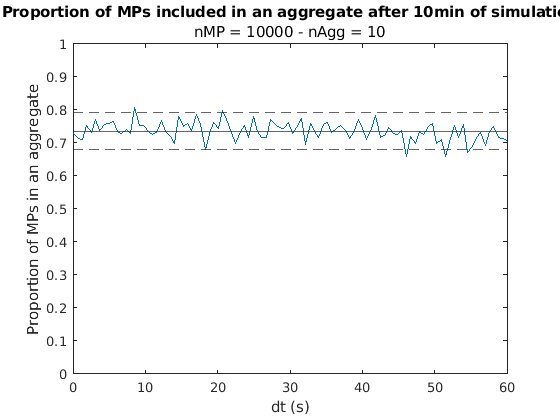


plot(dtTest, nMPagg), ylim([0 1])
yline(mean(nMPagg)+2*std(nMPagg), '--')
yline(mean(nMPagg)-2*std(nMPagg), '--')
yline(mean(nMPagg))
xlabel('dt (s)')
ylabel('Proportion of MPs in an aggregate')
title(['Proportion of MPs included in an aggregate after '...
num2str(tf/60) 'min of simulation'], ['nMP = ' num2str(nMP)...
' - nAgg = ' num2str(nAgg)])

#### Test particle motion coherence

zFinMat = cell2mat(zFinal);

Unrecognized function or variable 'zFinal'.

timeline = dt:dt:tf';

Move = nan(tf/dt-1,nMP);
for iZ = 1:(nMP)
    Move(:,iZ) = diff(-zFinMat(:,iZ));
end
maxWs = interp1(z,max([mp_list.Ws agg_list.Ws],[],2),z_);
minWs = interp1(z,min([mp_list.Ws agg_list.Ws],[],2),z_);
maxMove = max(maxWs.*dt + dK.*dt + sqrt(6.*K.*dt));
minMove = min(minWs.*dt + dK.*dt - sqrt(6.*K.*dt));

test = ~sum(sum(Move > maxMove)) && ~sum(sum(Move < minMove))


% 
% figure(1), clf, hold on,
% for iZ = 1:(nMP)
% % plot(timeline,-zFinMat(:,iZ),'DisplayName',num2str(mp_list(iZ).Index))
% plot((timeline(2:end)+timeline(1:end-1))/2, Move,'DisplayName',num2str(mp_list(iZ).Index))
% end  
% 
% yline(maxMove)
% yline(minMove)

Burd, A. B., & Jackson, G. A. (2009). Particle aggregation. In *Annual Review of Marine Science* (Vol. 1, pp. 65–90). Annual Reviews Inc. [https://doi.org/10.1146/annurev.marine.010908.163904](https://doi.org/10.1146/annurev.marine.010908.163904)

Huber, M. L., Perkins, R. A., Laesecke, A., Friend, D. G., Sengers, J. V., Assael, M. J., Metaxa, I. N., Vogel, E., Mareš, R., & Miyagawa, K. (2009). New international formulation for the viscosity of H2O. *Journal of Physical and Chemical Reference Data*, *38*(2), 101–125. [https://doi.org/10.1063/1.3088050](https://doi.org/10.1063/1.3088050)

McCave, I. N. (1984). Size spectra and aggregation of suspended particles in the deep ocean. *Deep Sea Research Part A, Oceanographic Research Papers*, *31*(4), 329–352. [https://doi.org/10.1016/0198-0149(84)90088-8](https://doi.org/10.1016/0198-0149(84)90088-8)